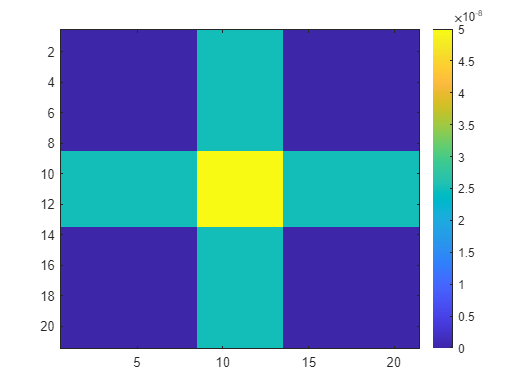

test_object{1} = imread('test_object.tif');
tumor_coords = rowcol_pairs(test_object);
rad_map = radiation_beam(tumor_coords(1).rows,tumor_coords(1).cols,0.5e-8,test_object{1});
figure;
imagesc(rad_map);
hold on;
colorbar;

function rad_map = radiation_beam(rows, cols, intensity, mri_image)
    % Initialize the radiation map with zeros
    rad_map = zeros(size(mri_image));

    % Loop over the identified pixel positions of the tumor and update the radiation map
    % Loop over rows
    for i = 1:length(rows)
        rad_map(rows(i), :) = rad_map(rows(i), :)+intensity; % the row of the single beam
    end
    
    % Loop over columns
    for j = 1:length(cols)
        rad_map(:, cols(j)) = rad_map(:, cols(j))+intensity; % the column of the single beam
    end
end

function tumor_coords = rowcol_pairs(patient_data)
    [rows,cols]=find(patient_data{:}>250);
    tumor_coords = struct("rows", rows, "cols", cols);
end
